# Lab7

h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


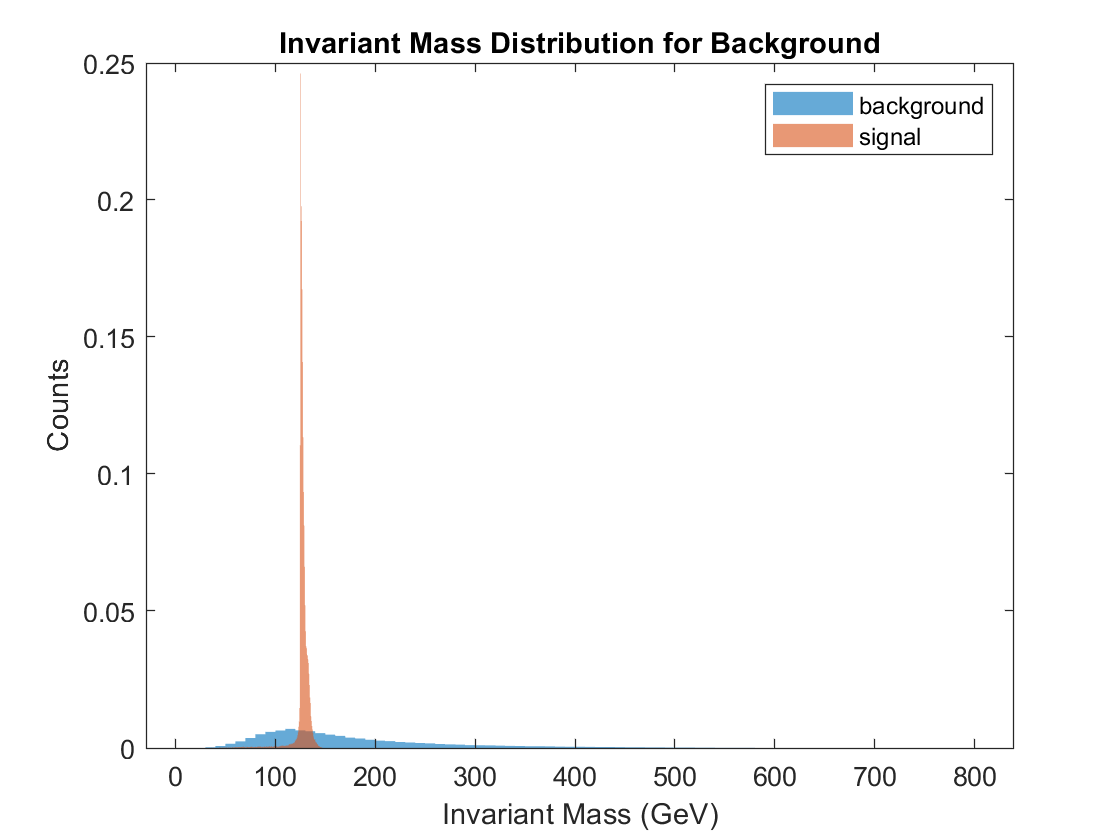

signal_dataset = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
background_dataset = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
signal_pt = signal_dataset(1,:);
signal_eta = signal_dataset(2,:);
signal_phi = signal_dataset(3,:);
signal_mass = signal_dataset(4,:);
signal_ee2 = signal_dataset(5,:);
signal_ee3 = signal_dataset(6,:);
signal_d2 = signal_dataset(7,:);
signal_angularity = signal_dataset(8,:);
signal_t1 = signal_dataset(9,:);
signal_t2 = signal_dataset(10,:);
signal_t3 = signal_dataset(11,:);
signal_t21 = signal_dataset(12,:);
signal_t32 = signal_dataset(13,:);
signal_KtDeltaR = signal_dataset(14,:);
background_pt = background_dataset(1,:);
background_eta = background_dataset(2,:);
background_phi = background_dataset(3,:);
background_mass = background_dataset(4,:);
background_ee2 = background_dataset(5,:);
background_ee3 = background_dataset(6,:);
background_d2 = background_dataset(7,:);
background_angularity = background_dataset(8,:);
background_t1 = background_dataset(9,:);
background_t2 = background_dataset(10,:);
background_t3 = background_dataset(11,:);
background_t21 = background_dataset(12,:);
background_t32 = background_dataset(13,:);
background_KtDeltaR = background_dataset(14,:);
figure;
histogram(background_mass,"EdgeColor","none","Normalization","pdf")
title("Invariant Mass Distribution");
hold on;
title("Invariant Mass Distribution for Background");
histogram(signal_mass,"EdgeColor","none","Normalization","pdf")
xlabel("Invariant Mass (GeV)"); 
ylabel("Counts");
legend("background","signal");

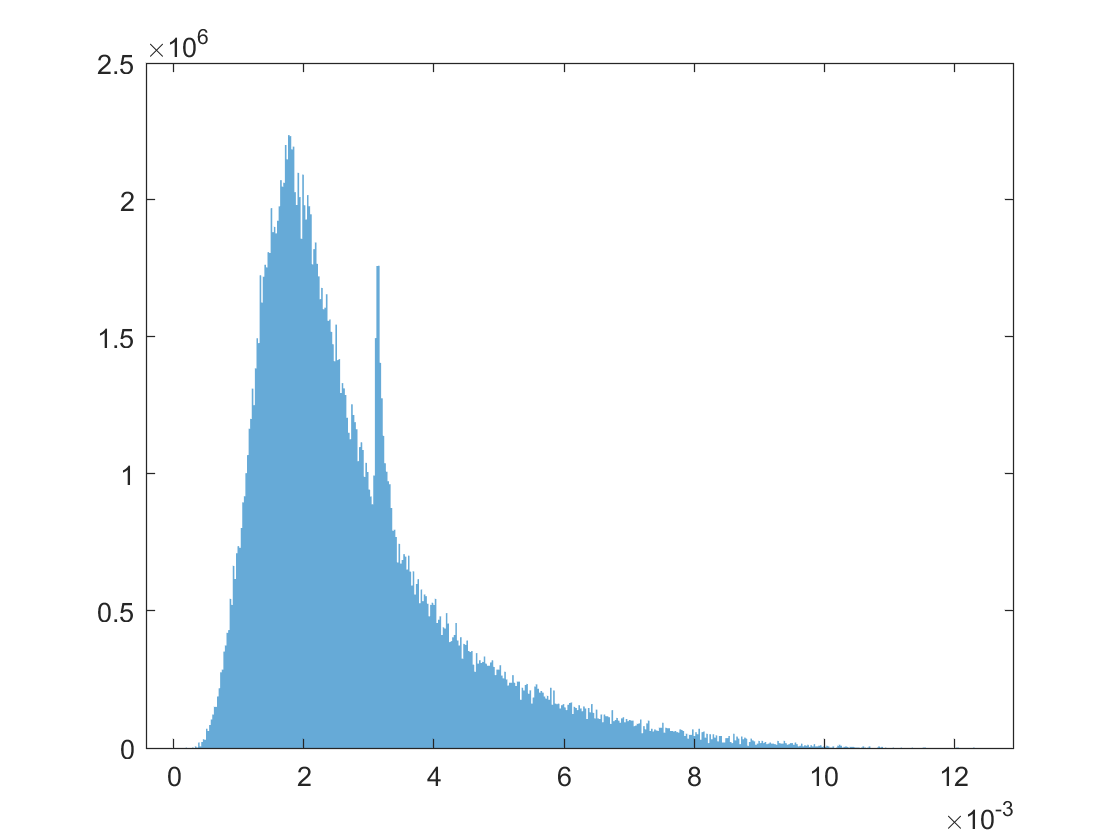

% background_mass = background_mass.'
% distribution = fitdist(background_mass,"Poisson")
% histogram(random(distribution,[1 50000]),"Normalization","pdf")
% x = 0:15;
% y = poisspdf(x,5);
%r_array = poissrnd(110,[50000 1]);
%histogram(r_array,"Normalization","pdf","EdgeColor","none")
figure;
background_mass_norm = background_mass / norm(background_mass);
signal_mass_norm = signal_mass / norm(signal_mass);
signal_mass_norm2 = signal_mass_norm;
background_mass_norm2 = background_mass_norm;
for i = 1:50
    signal_mass_norm = [signal_mass_norm signal_mass_norm2];
end
for i = 1:2000
    background_mass_norm = [background_mass_norm background_mass_norm2];
end
histogram([background_mass_norm signal_mass_norm],500,"EdgeColor","none","Normalization","pdf") 